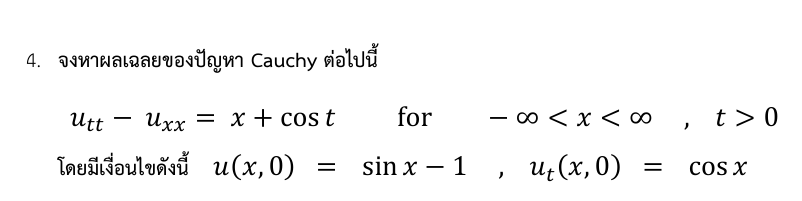

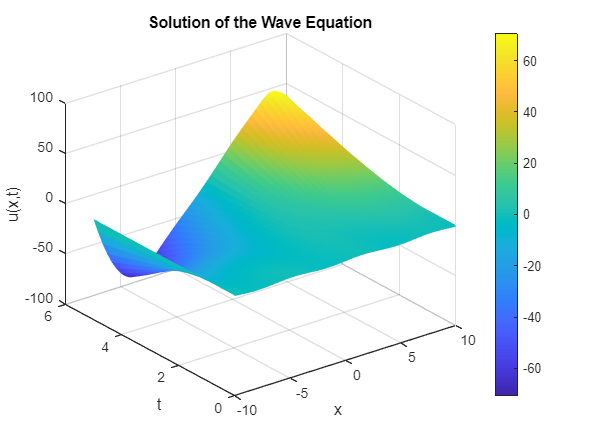

clear; clearvars; clf; clc;
% Parameters
L = 10;            % Spatial domain limit (-L to L)
N = 50;            % Number of spatial points
dx = 2 * L / (N-1); % Spatial step size
x = linspace(-L, L, N); % Spatial grid
T = 5;             % Time domain limit
dt = 0.01;         % Time step size
t = 0:dt:T;        % Time grid

% Wave equation parameters
c = 1; % Wave speed

% Initial conditions
u0 = sin(x) - 1;       % u(x, 0)
ut0 = cos(x);          % ut(x, 0)

% Initialize u for 3 time levels
u = zeros(N, length(t)); % Create the solution matrix
u(:,1) = u0;            % Initial condition u(x,0)

% Compute the second time level u(:,2) using Taylor expansion
for i = 2:N-1
    u(i,2) = u(i,1) + dt * ut0(i) + 0.5 * (dt^2) * ...
             ((u(i+1,1) - 2*u(i,1) + u(i-1,1)) / dx^2 + x(i) + cos(0)); % Using PDE
end

% Boundary conditions at the second time level
u(1,2) = 0; % Boundary at x = -L
u(N,2) = 0; % Boundary at x = L 

% Finite difference loop
for n = 2:length(t)-1
    for i = 2:N-1
        % Wave equation: utt - uxx = x + cos(t)
        u(i,n+1) = 2*u(i,n) - u(i,n-1) + (c*dt/dx)^2 * (u(i+1,n) - 2*u(i,n) + u(i-1,n)) ...
                   + dt^2 * (x(i) + cos(t(n)));
    end
    % Boundary conditions (u = 0 at boundaries)
    u(1,n+1) = 0; % Boundary at x = -L
    u(N,n+1) = 0; % Boundary at x = L
end

% Visualization
[X, T] = meshgrid(x, t);
figure;
surf(X, T, u', 'EdgeColor', 'none');
xlabel('x');
ylabel('t');
zlabel('u(x,t)');
title('Solution of the Wave Equation');
colorbar;